# Worksheet 3 - Edge Detection

## Mark Belanger

## October 25, 2024

## Load images

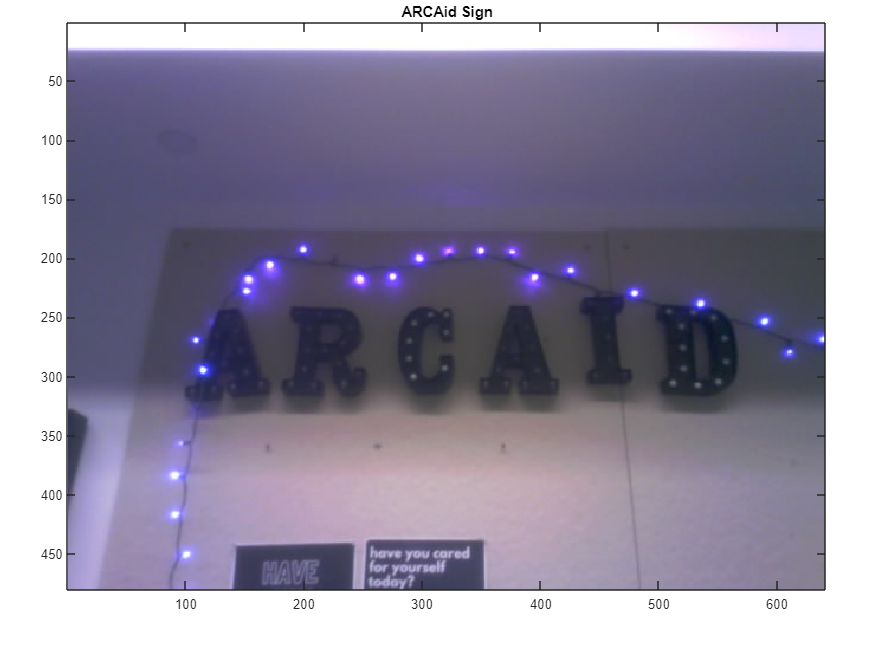

arcaid = imread("ARCAid.jpg");
image(arcaid);
title("ARCAid Sign");

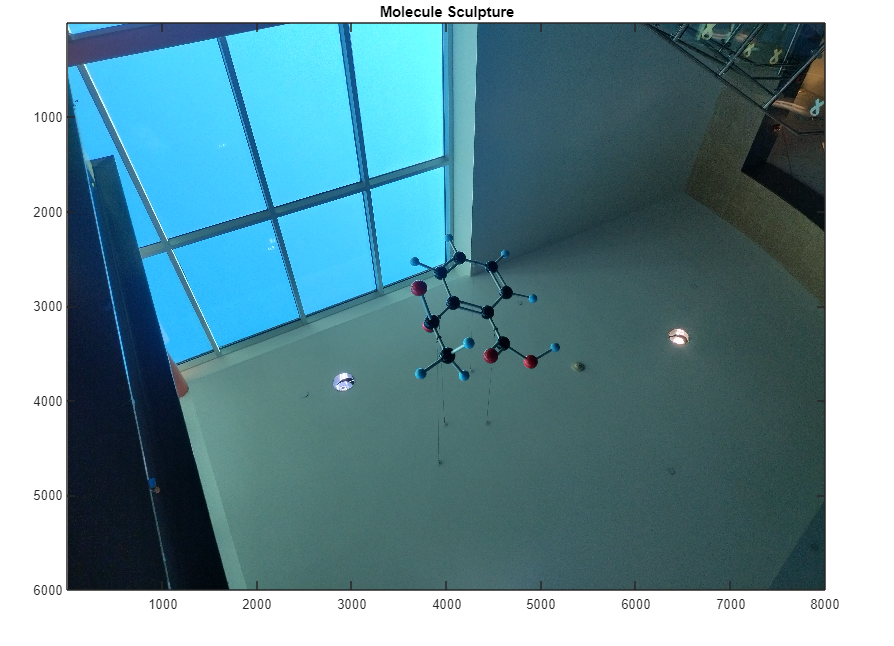

molecule = imread("molecule.jpg");
image(molecule);
title("Molecule Sculpture");

The molecule image displayed upside down and I don't know why but the processing works the same.

## 1) Performance of various gradient operators (total 40 points)

### a. Apply the following gradient operators to them using inbuilt MATLAB or Python function (‘edge’ function in MATLAB): (10 points)

#### i. Roberts

#### ARCaid

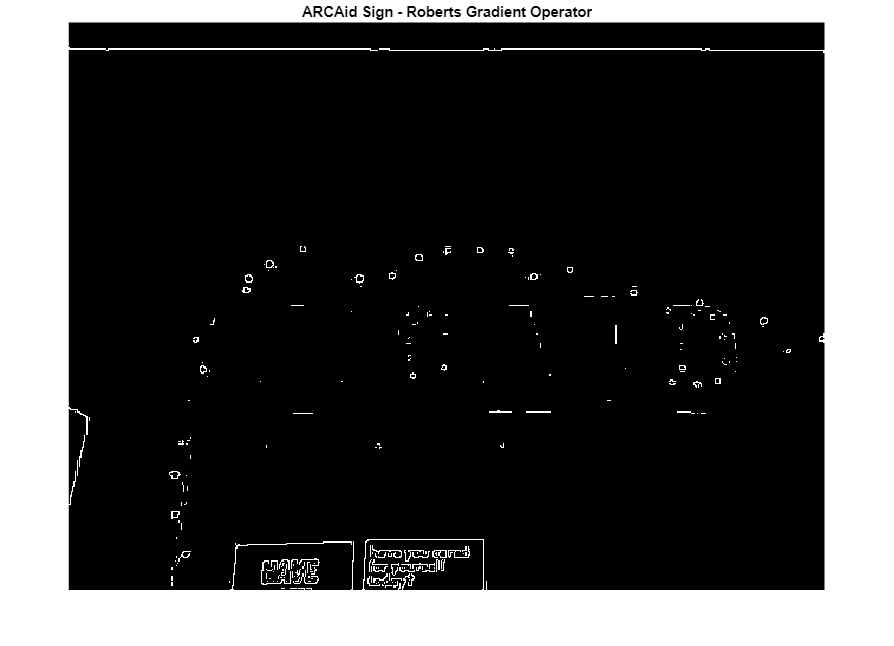

roberts_arcaid = edge(rgb2gray(arcaid),"roberts");
imshow(roberts_arcaid);
title("ARCAid Sign - Roberts Gradient Operator")

#### Molecule

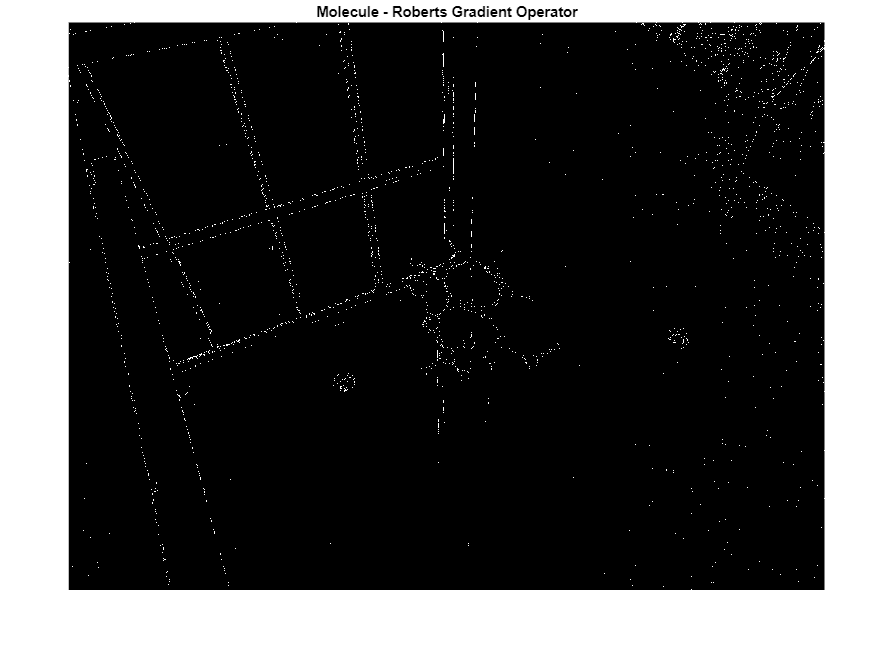

roberts_molecule = edge(rgb2gray(molecule),"roberts");
imshow(roberts_molecule);
title("Molecule - Roberts Gradient Operator")

#### ii. Prewitt

#### ARCaid

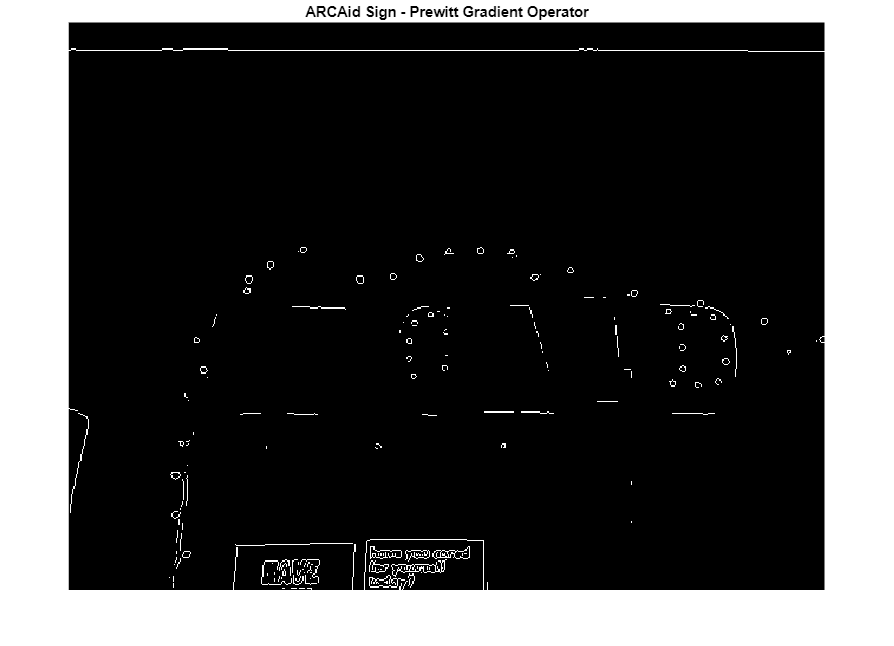

prewitt_arcaid = edge(rgb2gray(arcaid),"prewitt");
imshow(prewitt_arcaid);
title("ARCAid Sign - Prewitt Gradient Operator")

#### Molecule

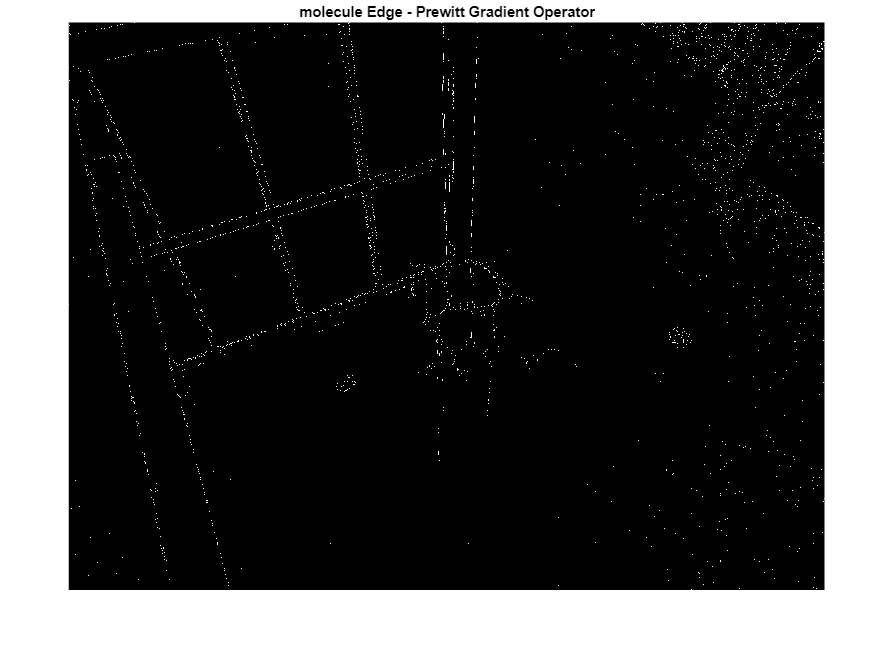

prewitt_molecule = edge(rgb2gray(molecule),"prewitt");
imshow(prewitt_molecule);
title("molecule Edge - Prewitt Gradient Operator")

#### iii. Sobel

#### ARCaid

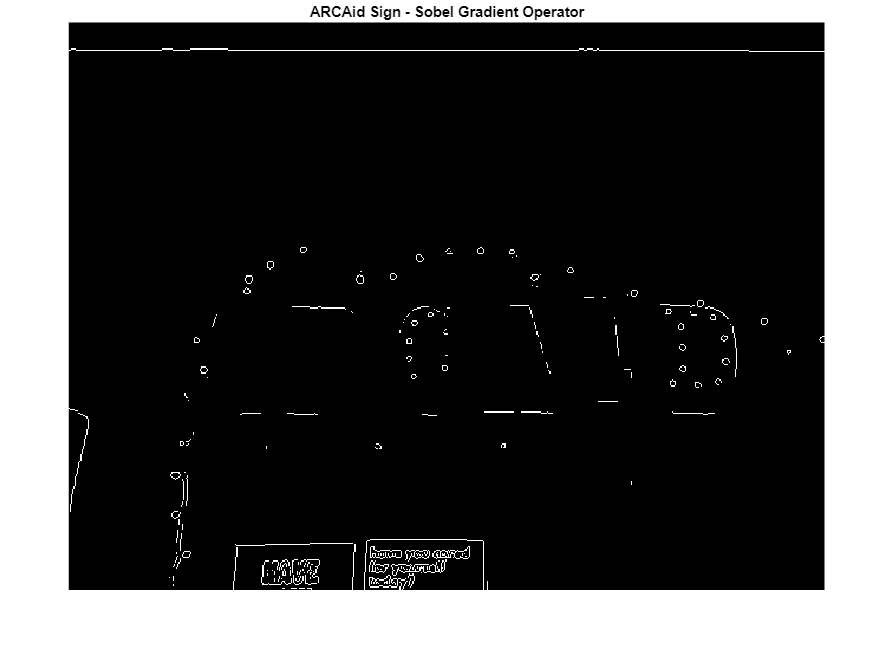

sobel_arcaid = edge(rgb2gray(arcaid),"sobel");
imshow(sobel_arcaid);
title("ARCAid Sign - Sobel Gradient Operator")

#### Molecule

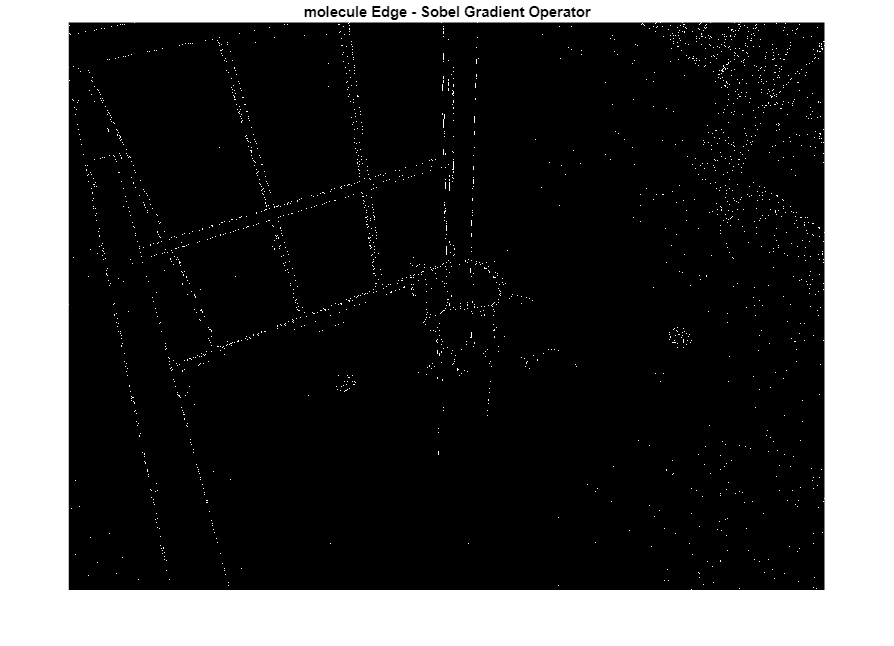

sobel_molecule = edge(rgb2gray(molecule),"sobel");
imshow(sobel_molecule);
title("molecule Edge - Sobel Gradient Operator")

### b. Add noise to each of the two images and now apply the three operators above to the images. (15 points)

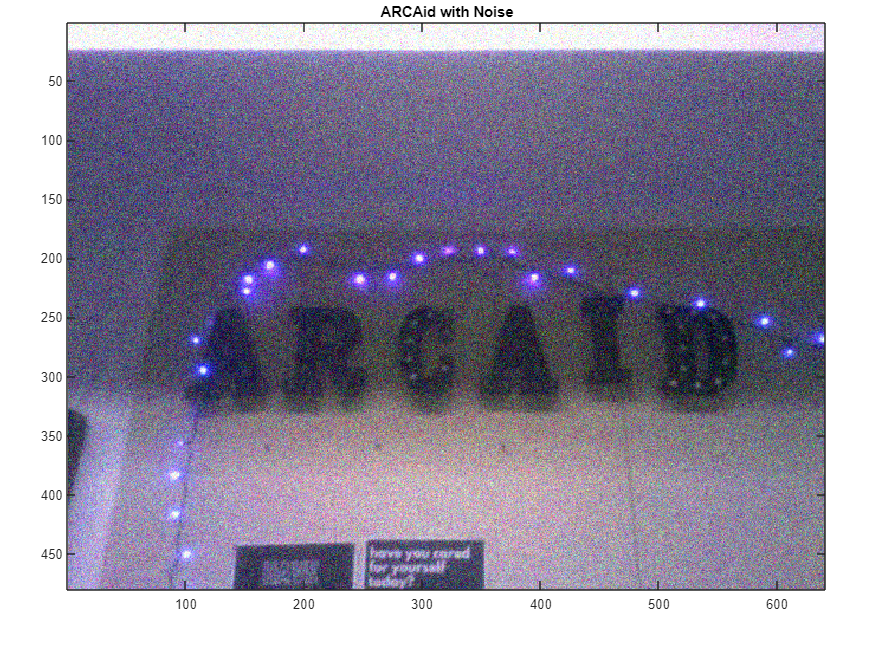

noisy_arcaid = imnoise(arcaid);
image(noisy_arcaid)
title("ARCAid with Noise")

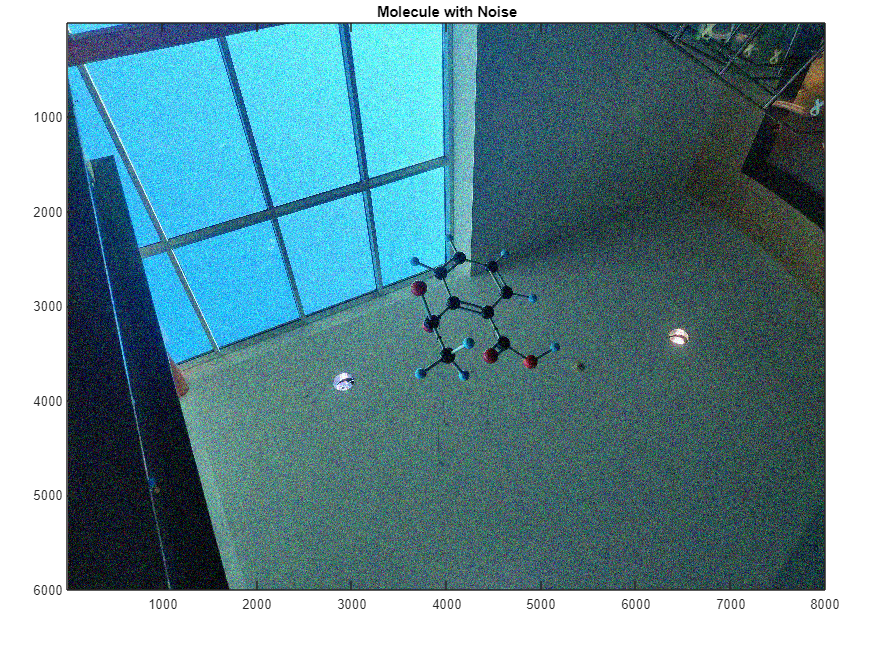


noisy_molecule = imnoise(molecule);
image(noisy_molecule)
title("Molecule with Noise")

#### i. Roberts

#### ARCaid

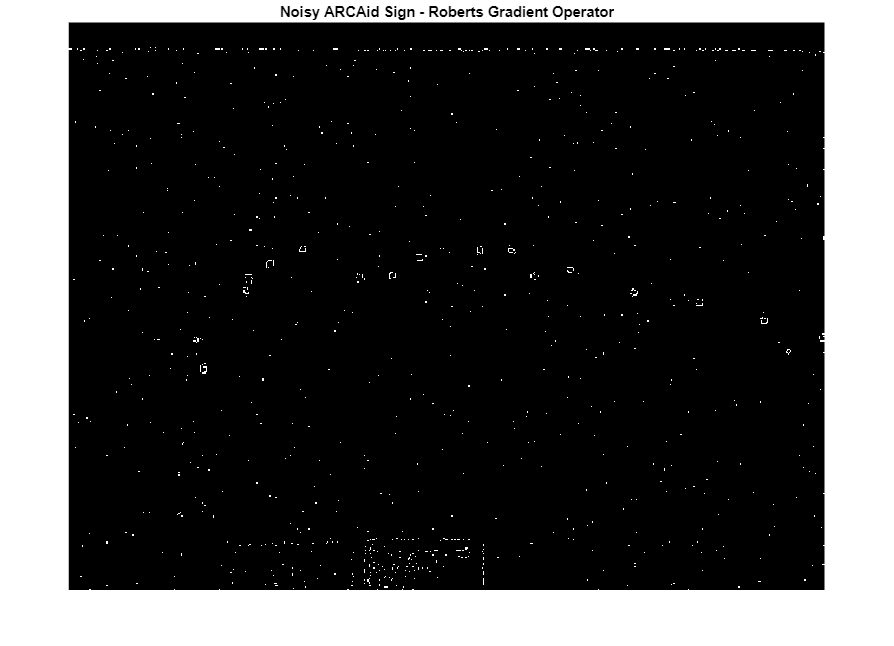

roberts_noisy_arcaid = edge(rgb2gray(noisy_arcaid),"roberts");
imshow(roberts_noisy_arcaid);
title("Noisy ARCAid Sign - Roberts Gradient Operator")

#### Molecule

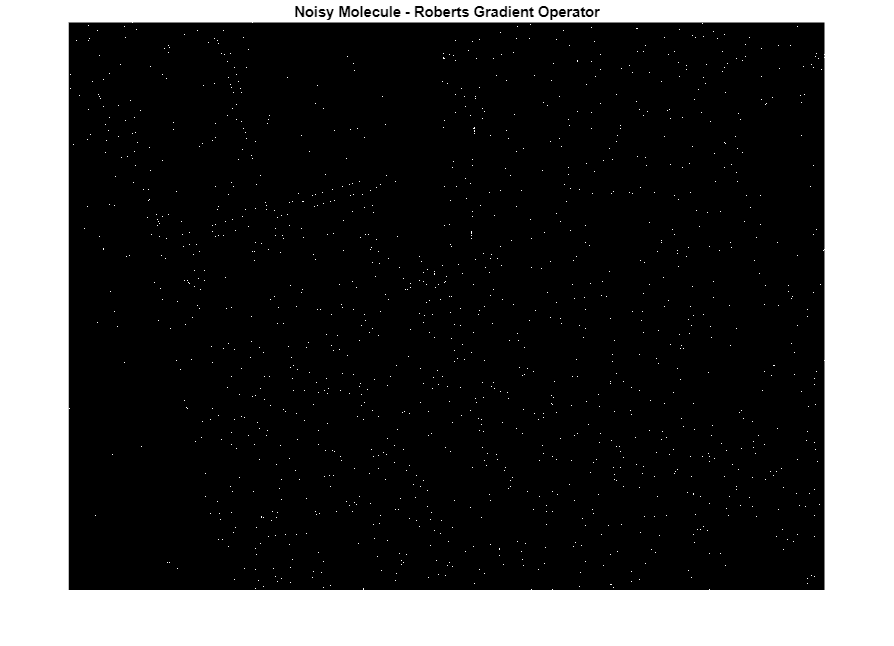

roberts_noisy_molecule = edge(rgb2gray(noisy_molecule),"roberts");
imshow(roberts_noisy_molecule);
title("Noisy Molecule - Roberts Gradient Operator")

#### ii. Prewitt

#### ARCaid

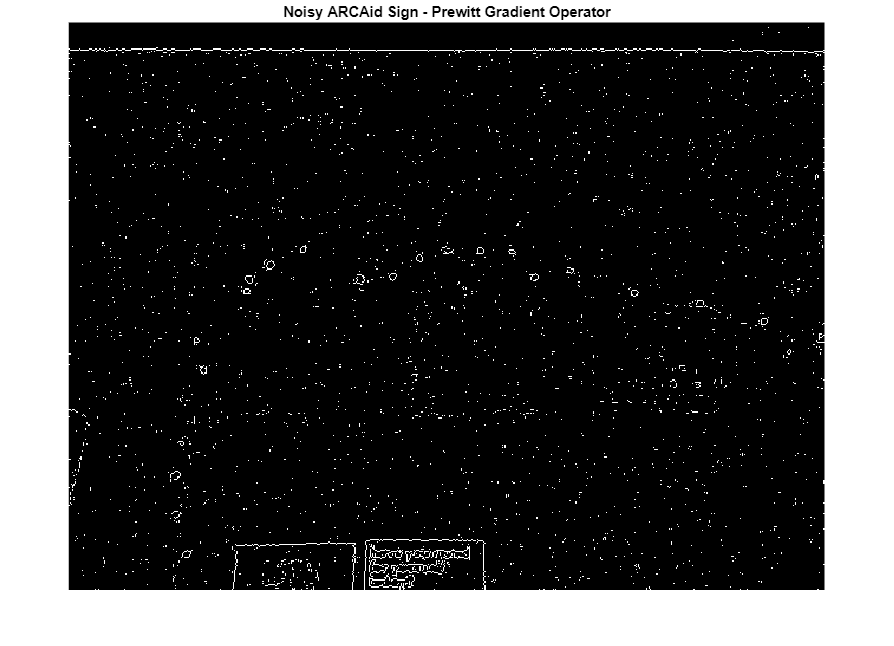

prewitt_noisy_arcaid = edge(rgb2gray(noisy_arcaid),"prewitt");
imshow(prewitt_noisy_arcaid);
title("Noisy ARCAid Sign - Prewitt Gradient Operator")

#### Molecule

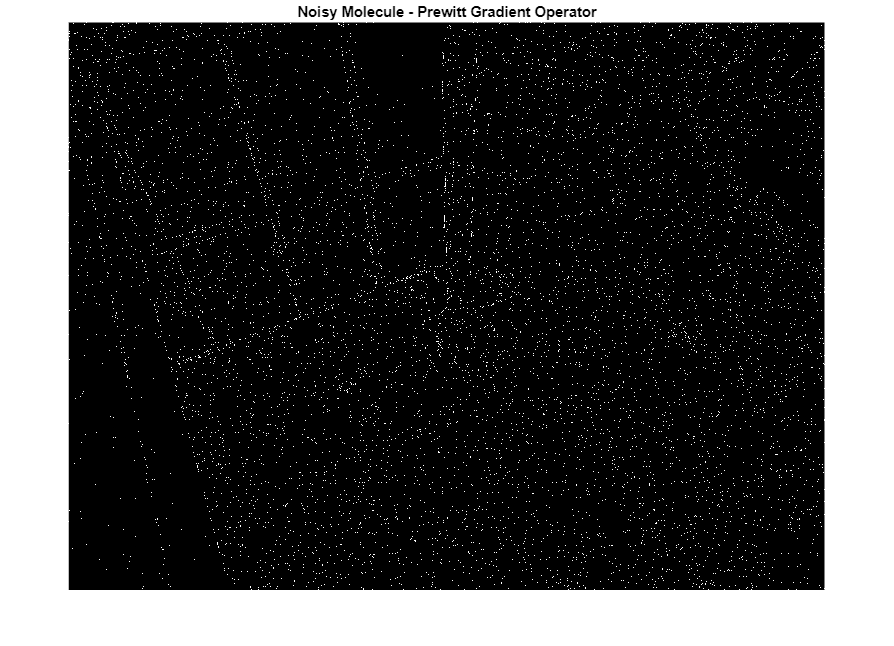

prewitt_noisy_molecule = edge(rgb2gray(noisy_molecule),"prewitt");
imshow(prewitt_noisy_molecule);
title("Noisy Molecule - Prewitt Gradient Operator")

#### iii. Sobel

#### ARCaid

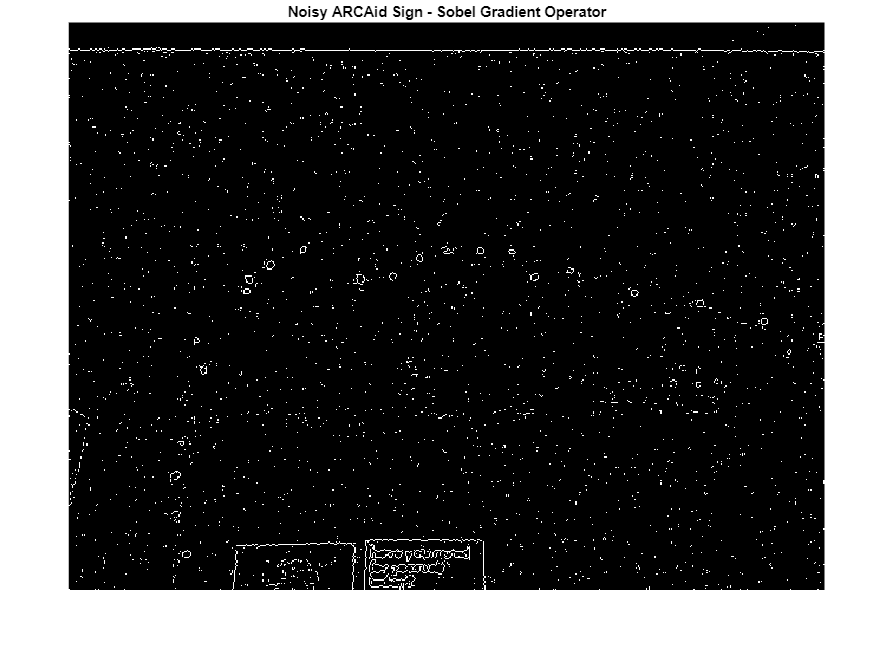

sobel_noisy_arcaid = edge(rgb2gray(noisy_arcaid),"sobel");
imshow(sobel_noisy_arcaid);
title("Noisy ARCAid Sign - Sobel Gradient Operator")

#### Molecule

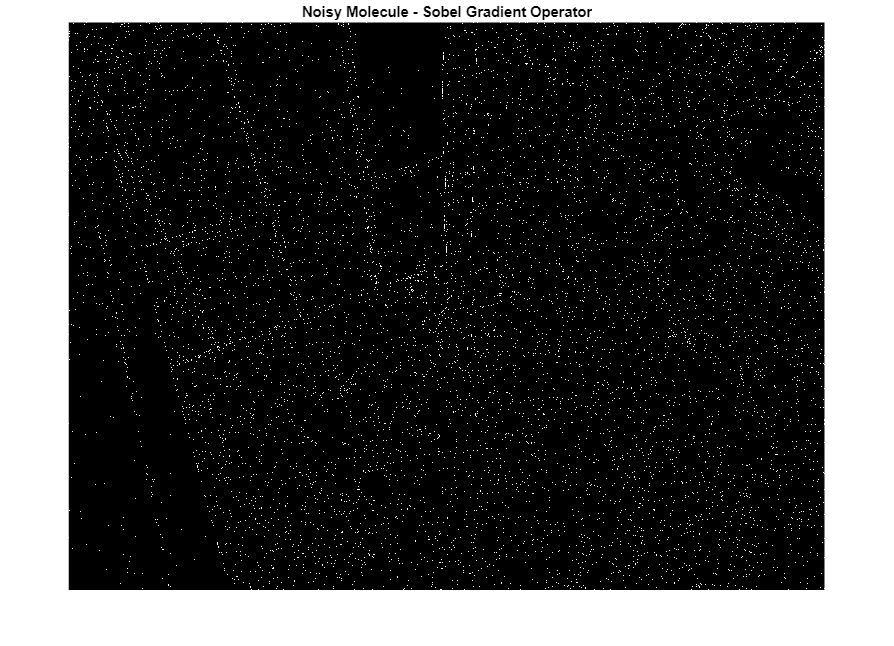

sobel_noisy_molecule = edge(rgb2gray(noisy_molecule),"sobel");
imshow(sobel_noisy_molecule);
title("Noisy Molecule - Sobel Gradient Operator")

### c. Compare the operators (15 points)

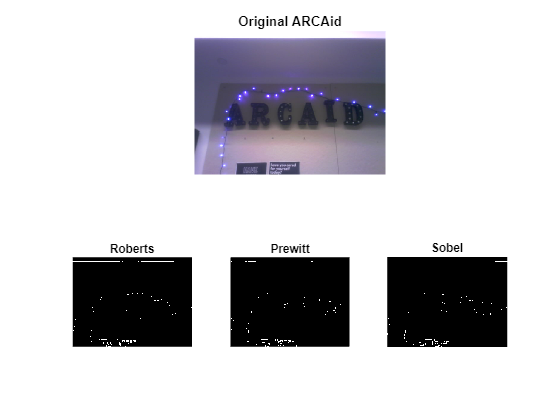

figure;
subplot(211)
imshow(arcaid)
title("Original ARCAid")
subplot(234);
imshow(roberts_arcaid)
title("Roberts")
subplot(235);
imshow(prewitt_arcaid);
title("Prewitt")
subplot(236);
imshow(sobel_arcaid)
title("Sobel")

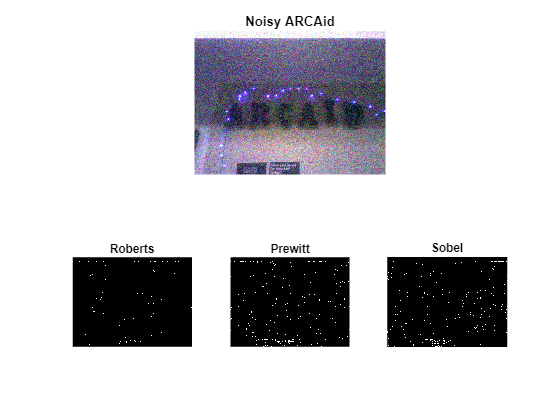

figure;
subplot(211)
imshow(noisy_arcaid)
title("Noisy ARCAid")
subplot(234);
imshow(roberts_noisy_arcaid)
title("Roberts")
subplot(235);
imshow(prewitt_noisy_arcaid);
title("Prewitt")
subplot(236);
imshow(sobel_noisy_arcaid)
title("Sobel")

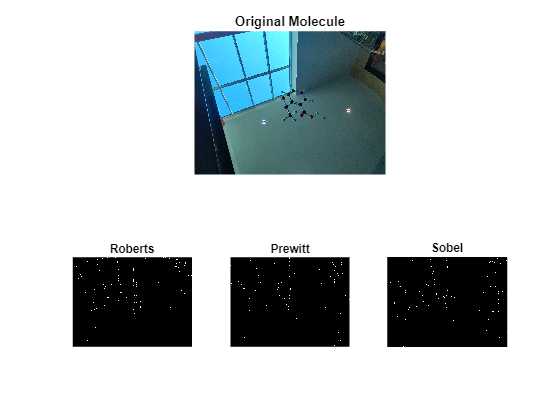

figure;
subplot(211)
imshow(molecule)
title("Original Molecule")
subplot(234);
imshow(roberts_molecule)
title("Roberts")
subplot(235);
imshow(prewitt_molecule);
title("Prewitt")
subplot(236);
imshow(sobel_molecule)
title("Sobel")

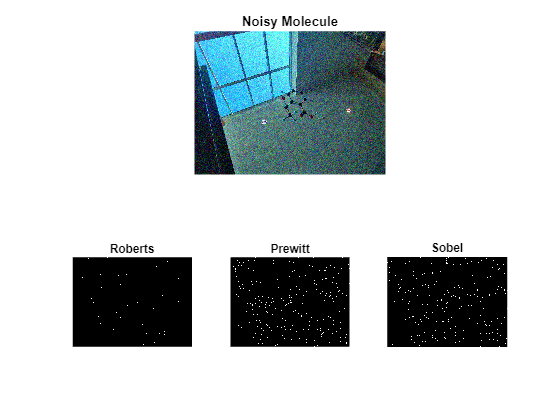

figure;
subplot(211)
imshow(noisy_molecule)
title("Noisy Molecule")
subplot(234);
imshow(roberts_noisy_molecule)
title("Roberts")
subplot(235);
imshow(prewitt_noisy_molecule);
title("Prewitt")
subplot(236);
imshow(sobel_noisy_molecule)
title("Sobel")

#### i. Comment on which operator performs better for each of your images

#### without noise

For the ARCAid image, Sobel worked the best. They all work relatively similarly well however Sobel does better at recognizing the edge of the wall/ceiling and shows the most detail in the edges of the lettering.

For the molecule image, Prewitt worked the best. The Prewitt operator did the best at detecting the edges of the window as well as the molecule sculpture itself.

#### ii. Comment on which operator performs better for each of your images

#### with noise.

For the noisy ARCAid sign image, the Prewitt and Sorbel seem to work equally well however the Robberts worked the worse. With Prewitt and Sorbel, the edges are noisy however the edges of the sign in the bottom of the image aswell as the edge from the wall at the top are highlighted. In Roberts, the sign and wall is detected but the edge is less clear.

The performance of the different operators on the molecule image is similar to that of the ARCAid image: Prewitt and Sorbel are best and Roberts is least good. The molecule itself is not highlighted well by any of the operators but the window edges are detected most well by Prewitt and Sorbel.

## 2) Some from-scratch coding (total 40 points)

### a. Write your own code to apply the 3x3 Sobel gradient operator to one of the images. (30 points)

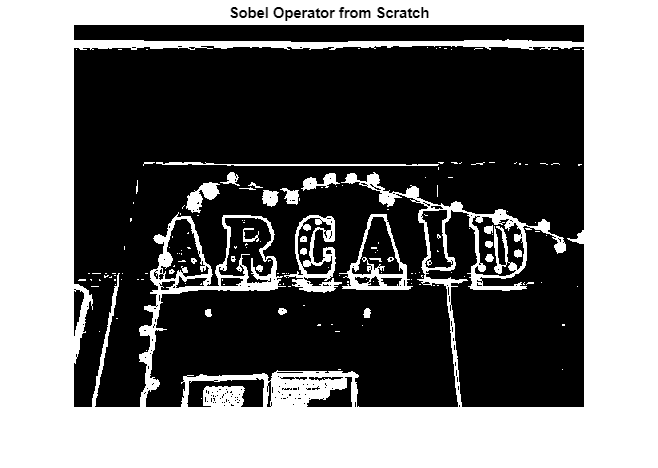

sobel_x = [
    -1, 0, 1;
    -2, 0, 2;
    -1, 0, 1;
];

sobel_y = sobel_x';

arcaid_sobel_x = conv2(rgb2gray(arcaid), sobel_x);
arcaid_sobel_y = conv2(rgb2gray(arcaid), sobel_y);

arcaid_sobel = sqrt(arcaid_sobel_x.^2 + arcaid_sobel_y.^2);

% The range of a double is quite large and some values are near 0
% but are not so this assumes anything less than the mean is a 0 
% and everything greater than is a 1. This converts the image into 
% binary and makes the edges more apparent.
arcaid_sobel = arcaid_sobel > mean(arcaid_sobel, "all");

figure
imshow(arcaid_sobel)
title("Sobel Operator from Scratch")

### b. Comment on whether your own code performs better or worse than the inbuilt functions. (10 points)

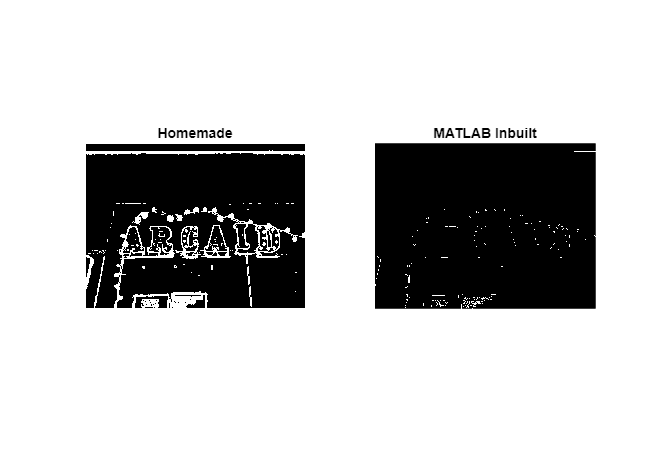

subplot(121)
imshow(arcaid_sobel)
title("Homemade")

subplot(1,2,2)
imshow(sobel_arcaid)
title("MATLAB Inbuilt")

I think my code performs better than the inbuilt MATLAB function. My code produces an image that far better outlines the ARCAid sign, posters, wall, ceiling, etc. The edges are thicker in my implementation but I think it better defines the image despite loosing some of the detail. My implementation is worse at showing the letters on the poster though. The letter on the poster can almost be read when using the MATLAB function but they are blured out in my implementation.